# Parameters of single-photon scanning microscope

% Jonghwan Lee, Mar 2021

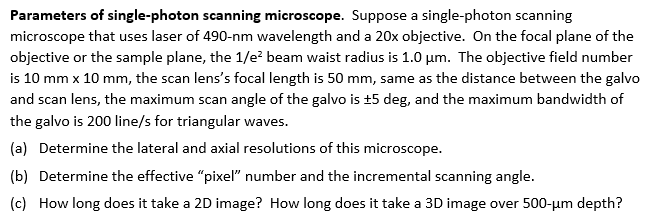

Constants.  All lengths are in [mm].

clear

lam = 490e-6;
mObj = 20;
w0Samp = 1.0e-3;
objFnum = 10;  % objective field number
fScan = 50;
galvoAngMax = 2*5/180*pi;  % in radian, full angle
galvoSpeed = 200;  % line/s

## (a) Resolution

k = 2*pi/lam;
zRayleighSamp = 1/2*k*w0Samp^2;  % Rayleigh range on the sample plane

fwhmSamp = 2*sqrt(2*log(2)) * w0Samp/2

fwhmSamp = 0.0012

dofSamp = 2 * zRayleighSamp

dofSamp = 0.0128

## (b) Sampling interval and FOV

dxSamp = fwhmSamp / 2;  % Nyquist
fovSamp = min( objFnum , fScan * galvoAngMax ) / mObj

fovSamp = 0.4363

pixNum = round(fovSamp / dxSamp)  % per side

pixNum = 741

galvoAngStep = dxSamp * mObj / fScan * 180/pi  % in deg

galvoAngStep = 0.0135

## (c) Imaging time

zMax = 500e-3;  % total depth to scan
timeArea = pixNum / galvoSpeed  % lines in Y axis / [line/s]

timeArea = 3.7050

dz = dofSamp/2;  % axial sampling interval
pixNumZ = round(zMax/dz)

pixNumZ = 78

timeVol = pixNumZ * timeArea

timeVol = 288.9900